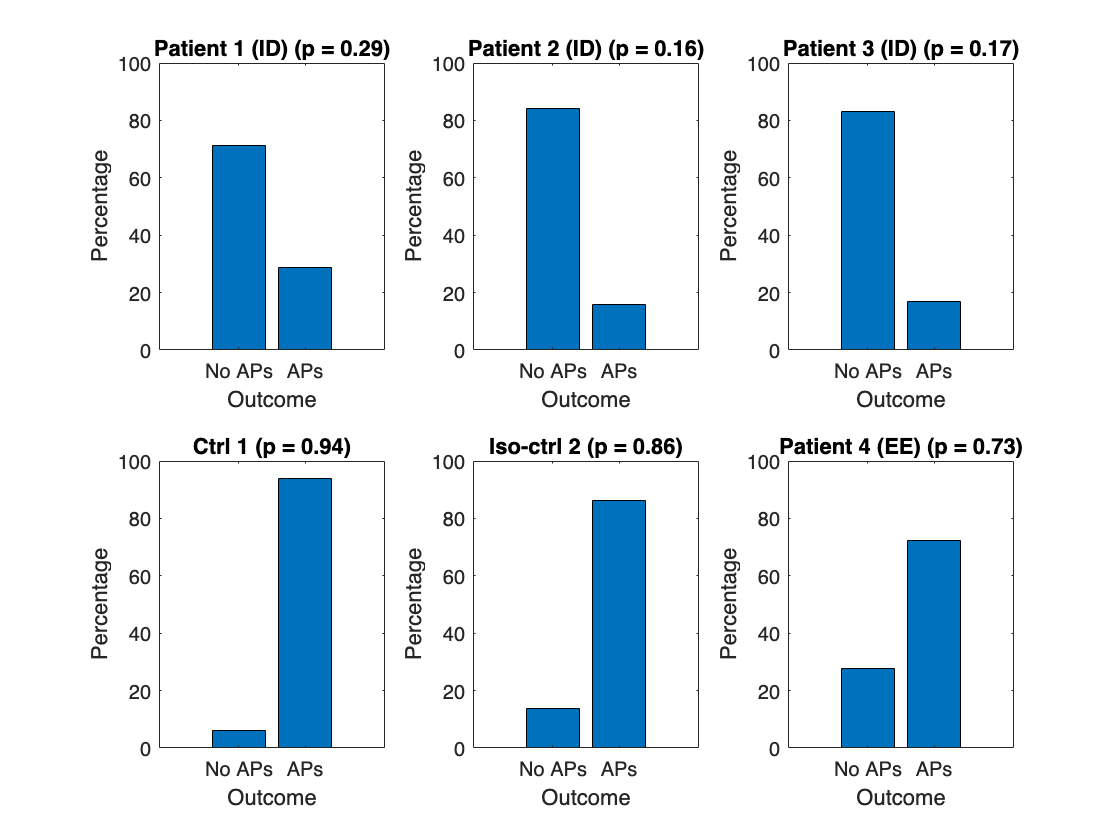

Simulation 1 (Patient 1 (ID), p = 0.29):


7116 No APs, 2884 APs, simulated p = 0.2884, empirical p = 0.2901


Simulation 2 (Patient 2 (ID), p = 0.16):


8410 No APs, 1590 APs, simulated p = 0.1590, empirical p = 0.1562


Simulation 3 (Patient 3 (ID), p = 0.17):


8300 No APs, 1700 APs, simulated p = 0.1700, empirical p = 0.1678


Simulation 4 (Ctrl 1, p = 0.94):


611 No APs, 9389 APs, simulated p = 0.9389, empirical p = 0.9411


Simulation 5 (Iso-ctrl 2, p = 0.86):


1367 No APs, 8633 APs, simulated p = 0.8633, empirical p = 0.8606


Simulation 6 (Patient 4 (EE), p = 0.73):


2777 No APs, 7223 APs, simulated p = 0.7223, empirical p = 0.7315


% Set number of repetitions (samples) 
num_repetitions = 6; % 3 reps of ID patient cell lines, 3 reps for controls and EE patient lines

figure; % Create a new figure

for rep = 1:num_repetitions
    % Generate a random probability between 0.15 and 0.50 for the ID patients
    % Generate a random probability between 0.7 and 0.95 for the EE patient and contorl lines
    if rep <= 3
        min_probability = 0.15;
        max_probability = 0.50;
        patient_label = sprintf('Patient %d (ID)', rep);
    else
        min_probability = 0.7;
        max_probability = 0.95;
        if rep == 4
            patient_label = 'Ctrl 1';
        elseif rep == 5
            patient_label = 'Iso-ctrl 2';
        else
            patient_label = 'Patient 4 (EE)';
        end
    end
    p = min_probability + (max_probability - min_probability) * rand();
    
    fprintf('Simulation %d (%s, p = %.2f):\n', rep, patient_label, p);
    
    % Now generate lots of Bernoulli trials to check if it is converging on the appropriate probability
    % Number of Bernoulli trials to simulate
    N = 10000;

    % Use rand() to generate outcomes (an array) from a lot of trials
    outcomes = rand(1, N) < p;

    % Count "No APs" (zeros) and "APs" (ones)
    num_no_aps = sum(outcomes == 0);
    num_aps = sum(outcomes == 1);

    % Display the results
    fprintf('%d No APs, %d APs, simulated p = %.4f, empirical p = %.4f\n', ...
        num_no_aps, num_aps, mean(outcomes), p);

    % Calculate percentages
    total_samples = numel(outcomes);
    percentage_no_aps = (num_no_aps / total_samples) * 100;
    percentage_aps = (num_aps / total_samples) * 100;

    % Create a subplot for each repetition
    subplot(2, 3, rep); % 2 rows, 3 columns
    bar([0, 1], [percentage_no_aps, percentage_aps], 'stacked'); % Stack bars vertically
    xlabel('Outcome');
    ylabel('Percentage');
    title(sprintf('%s (p = %.2f)', patient_label, p));
    set(gca, 'XTickLabel', {'No APs', 'APs'}); % Label the zeros as "No APs"
    ylim([0, 100]); % Set Y-axis limit to 0-100%
end